## Non linear project 2023

By .. and ..

clc
clear 
close all

### Physical system constants

K = 19;                     % [-]
k_hat = 25;                 % [-]
tau = 25;                   % [mm]
p_x_range = [-100, 100];    % [mm]
p_y = 0;                    % [mm]
p_z = 1;                    % [mm]
r_0 = 6.5;                  % [Ohm]
r_1 = 11;                   % [Ohm]
m = 2;                      % [kg]
g = 10;                     % [m/s^2]

### Question (1)

p_x_t = 0; % simple p_x to test with

% function to generate Gm for different p_x
Gm_px_f = @(p_x, p_z) gamma_matrix(p_x, K, k_hat, tau, p_z);

### Question (2)

(see overleaf doc)

% create symbolic gamma matrix
syms tau p_x

c_1 = (4/3)*tau;
c_2 = 2*(4/3)*tau;
c_3 = 3*(4/3)*tau;
alpha_1 = (pi/tau) * (p_x - c_1);
alpha_2 = (pi/tau) * (p_x - c_2);
alpha_3 = (pi/tau) * (p_x - c_3);

A = [sin(alpha_1) sin(alpha_2) sin(alpha_3);
     cos(alpha_1) cos(alpha_2) cos(alpha_3);
     p_z*sin(alpha_1)-(p_x-c_1)*cos(alpha_1) p_z*sin(alpha_2)-(p_x-c_2)*cos(alpha_2) p_z*sin(alpha_3)-(p_x-c_3)*cos(alpha_3);
];

rref(A)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

### Question (3)

(see overleaf doc)

### Question (4)

(see overleaf doc)

% create diagonal matrix as specified
r = repelem(r_0, K);
r(1) = r_1; 
r(end) = r_1;
R = diag(r);

### Question (5)

% w_desired for this question
w_des = [20; 20; 0];

% solve Ax = b 
i_com = min_abs_power(R, Gm_px_f(p_x_t,p_z), w_des);

% power consumed by this system
P_com = i_com' * R * i_com;

### Question (6)

% create different values for p_x
px_t = p_x_range(1):p_x_range(2);
i_com_arr = zeros(K, length(px_t));
P_com_arr = zeros(1, length(px_t));

% loop over all p_x
for i = 1:length(px_t)
    % get p_x and its corresponding Gamma matrix
    p_x_i = px_t(i);
    Gm_i = Gm_px_f(p_x_i, 1);

    % solve A\x for every p_x
    i_com = min_abs_power(R, Gm_i, w_des);
    i_com_arr(:,i) = i_com; 

    % compute power
    P_com_arr(i) = i_com' * R * i_com;
end

Make plot for $P$:

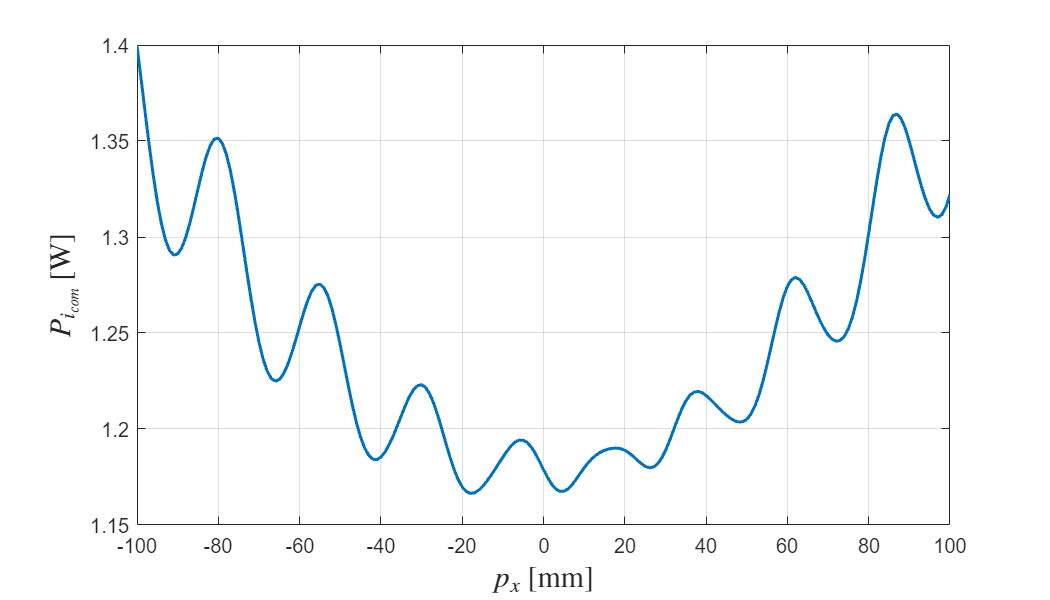

figure(1)
x0=150;
y0=150;
width=700;
height=400;
set(gcf,'position',[x0,y0,width,height])
plot(px_t,P_com_arr, 'LineWidth', 1.5)
grid on
ylabel('$P_{i_{com}}$ [W]', "FontSize", 15,'Interpreter','latex')
xlabel('$p_x$ [mm]', "FontSize", 15,'Interpreter','latex')
xlim(p_x_range)

Make plot for current distributions $i_{com}$:

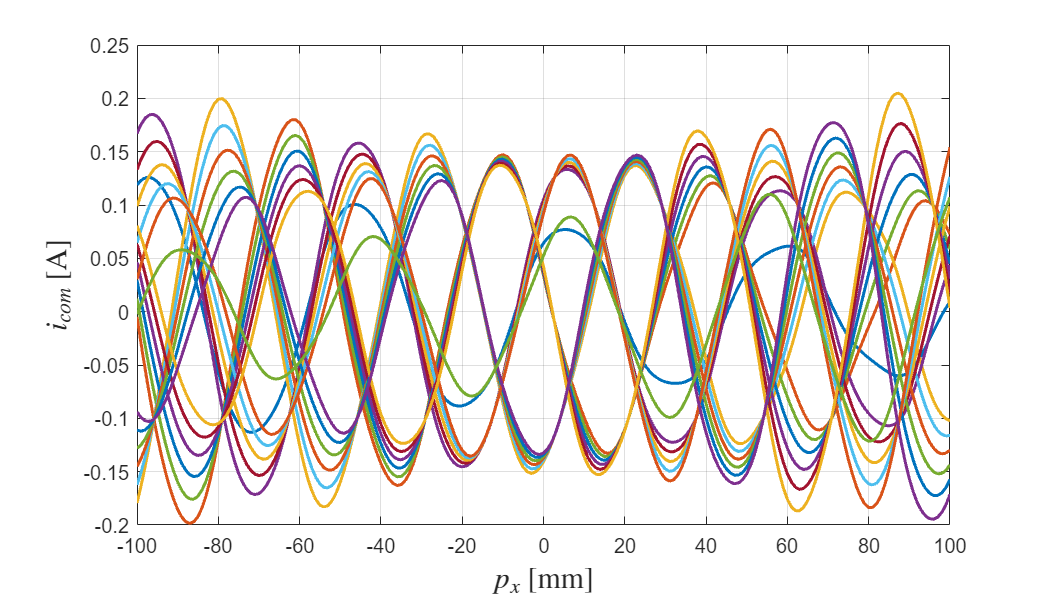

figure(2)
set(gcf,'position',[x0,y0,width,height])
plot(px_t,i_com_arr, 'LineWidth', 1.5)
grid on
ylabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
xlabel('$p_x$ [mm]', "FontSize", 15,'Interpreter','latex')
xlim(p_x_range)

figure
set(gcf,'position',[x0,y0,width,height])
h = histogram(i_com_arr, 'Normalization','probability')

h =   Histogram with properties:

             Data: [19×201 double]
           Values: [0.0063 0.0152 0.0427 0.0830 0.0759 0.0631 0.0573 0.0555 0.0518 0.0490 0.0477 0.0521 0.0581 0.0589 0.0642 0.0757 0.0812 0.0416 0.0160 0.0039 7.8555e-04]
          NumBins: 21
         BinEdges: [-0.2000 -0.1800 -0.1600 -0.1400 -0.1200 -0.1000 -0.0800 -0.0600 -0.0400 -0.0200 0 0.0200 0.0400 0.0600 0.0800 0.1000 0.1200 0.1400 0.1600 0.1800 0.2000 0.2200]
         BinWidth: 0.0200
        BinLimits: [-0.2000 0.2200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


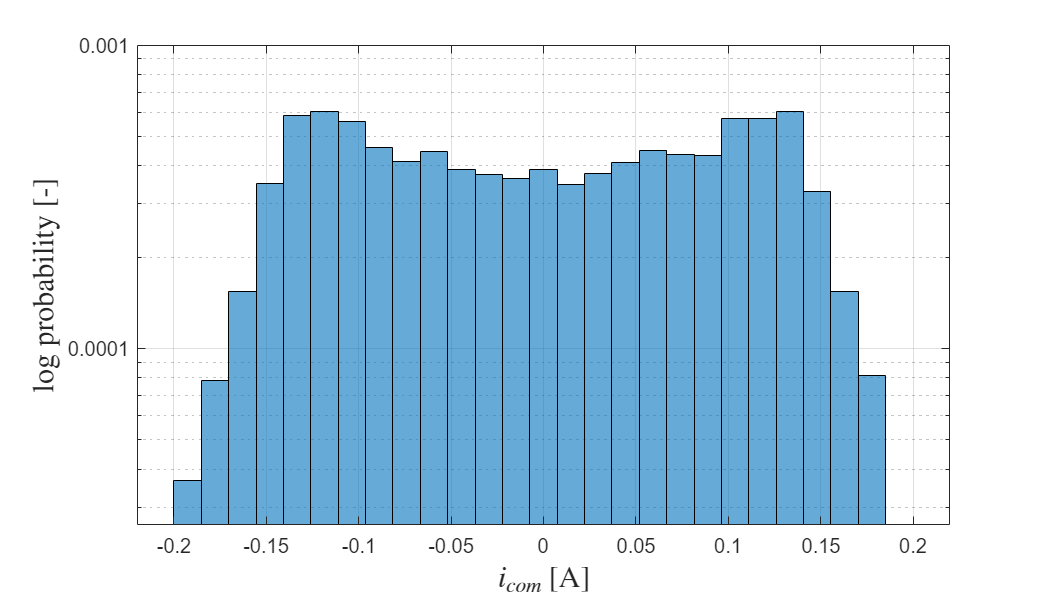

h.BinEdges = -0.2:0.01:0.2;
h.NumBins = 27;
set(gca,'yscale','log')
yticklabels({'0.0001','0.001','0.01','0.1','1'})
grid on
xlabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
ylabel('log probability [-]', "FontSize", 15,'Interpreter','latex')

### Question 7

Minimize the maximum current $i_k$

% test value for p_x = 80mm, because in this area the currents are larger
p_x_t = 80;

% gamma matrix
Gm_px = Gm_px_f(p_x_t, 1);
i_com = min_max_abs_cur(Gm_px, w_des)

i_com =    -0.0034
   -0.1150
    0.1150
   -0.1150
    0.1132
    0.1150
   -0.1150
    0.1150
    0.1150
   -0.1150


### Question 8

% create different values for p_x
px_t = p_x_range(1):p_x_range(2);
i_com_arr = zeros(K, length(px_t));

% loop over all p_x
for i = 1:length(px_t)
    % get p_x and its corresponding Gamma matrix
    Gm_i = Gm_px_f(px_t(i), 1);

    % solve for i_com
    i_com = min_max_abs_cur(Gm_i, w_des);
    i_com_arr(:,i) = i_com; 
end

Make plot for current distributions $i_{com}$:

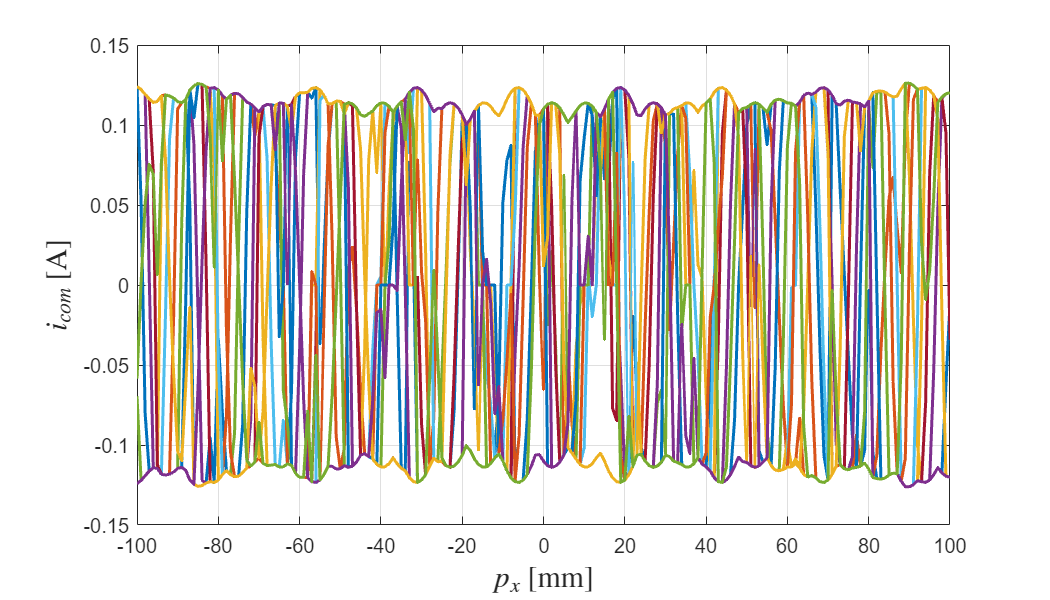

figure(3)
set(gcf,'position',[x0,y0,width,height])
plot(px_t,i_com_arr, 'LineWidth', 1.5)
grid on
ylabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
xlabel('$p_x$ [mm]', "FontSize", 15,'Interpreter','latex')
xlim(p_x_range)

figure
set(gcf,'position',[x0,y0,width,height])
h = histogram(i_com_arr, 'Normalization','probability')

h =   Histogram with properties:

             Data: [19×201 double]
           Values: [0.1074 0.3399 0.0079 0.0100 0.0097 0.0073 0.0094 0.0283 0.0065 0.0071 0.0110 0.0126 0.3367 0.1063]
          NumBins: 14
         BinEdges: [-0.1400 -0.1200 -0.1000 -0.0800 -0.0600 -0.0400 -0.0200 0 0.0200 0.0400 0.0600 0.0800 0.1000 0.1200 0.1400]
         BinWidth: 0.0200
        BinLimits: [-0.1400 0.1400]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


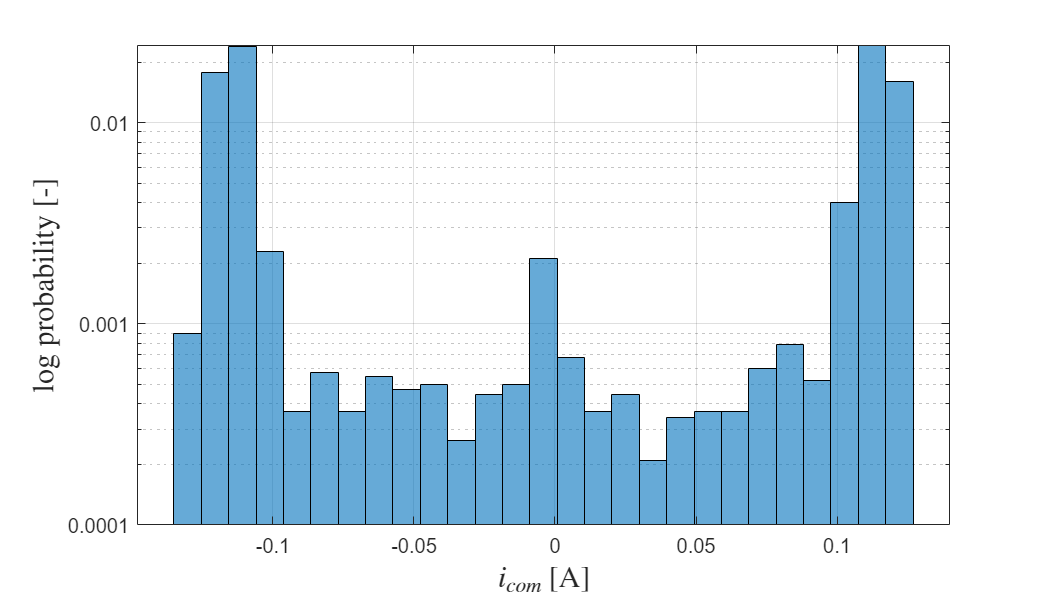

% h.BinEdges = [-1.5:1.5];
h.NumBins = 27;
set(gca,'yscale','log')
yticklabels({'0.0001','0.001','0.01','0.1','1'})
grid on
xlabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
ylabel('log probability [-]', "FontSize", 15,'Interpreter','latex')

### Question 9

% create different values for p_x
px_t = p_x_range(1):p_x_range(2);
i_com_arr = zeros(K, length(px_t));

% loop over all p_x
for i = 1:length(px_t)
    % get p_x and its corresponding Gamma matrix
    Gm_i = Gm_px_f(px_t(i), 1);

    % solve for i_com
    i_com = min_active_coils(Gm_i, w_des);
    i_com_arr(:,i) = i_com; 
end

Make plot for current distributions $i_{com}$:

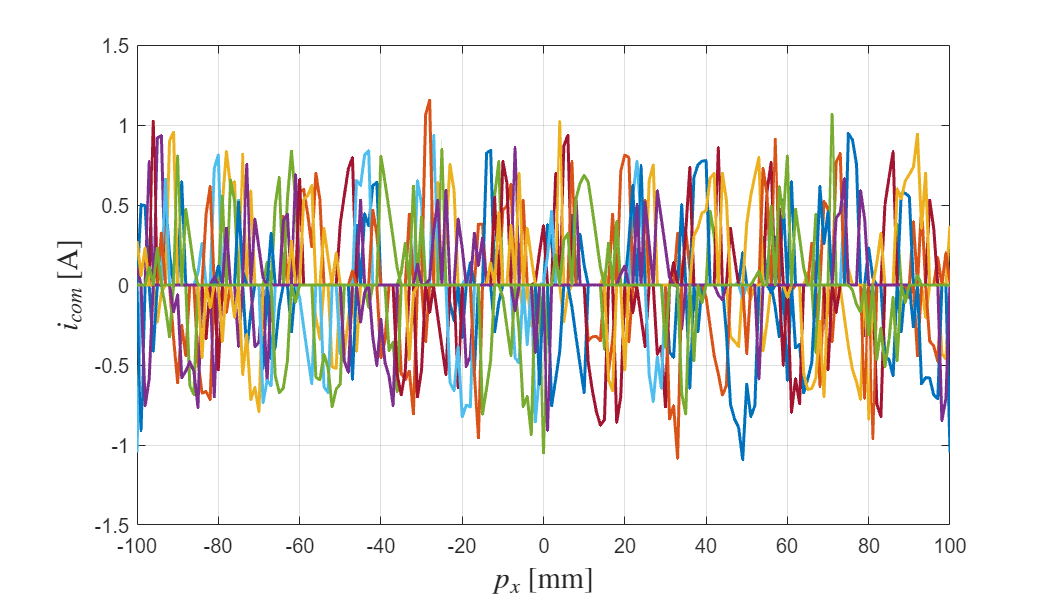

close all
figure
set(gcf,'position',[x0,y0,width,height])
plot(px_t,i_com_arr, 'LineWidth', 1.5)
grid on
ylabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
xlabel('$p_x$ [mm]', "FontSize", 15,'Interpreter','latex')
xlim(p_x_range)

close all
figure
set(gcf,'position',[x0,y0,width,height])
h = histogram(i_com_arr, 'Normalization','probability')

h =   Histogram with properties:

             Data: [19×201 double]
           Values: [5.2370e-04 7.8555e-04 5.2370e-04 7.8555e-04 0.0010 0.0029 0.0034 0.0031 0.0058 0.0055 0.0073 0.0055 0.0058 0.0060 0.0058 0.0052 0.0037 0.0037 0.0024 0.0031 0.0031 0.0031 0.8466 0.0031 0.0045 0.0018 0.0034 0.0047 … ] (1×46 double)
          NumBins: 46
         BinEdges: [-1.1000 -1.0500 -1 -0.9500 -0.9000 -0.8500 -0.8000 -0.7500 -0.7000 -0.6500 -0.6000 -0.5500 -0.5000 -0.4500 -0.4000 -0.3500 -0.3000 -0.2500 -0.2000 -0.1500 -0.1000 -0.0500 0 0.0500 0.1000 0.1500 0.2000 0.2500 0.3000 … ] (1×47 double)
         BinWidth: 0.0500
        BinLimits: [-1.1000 1.2000]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

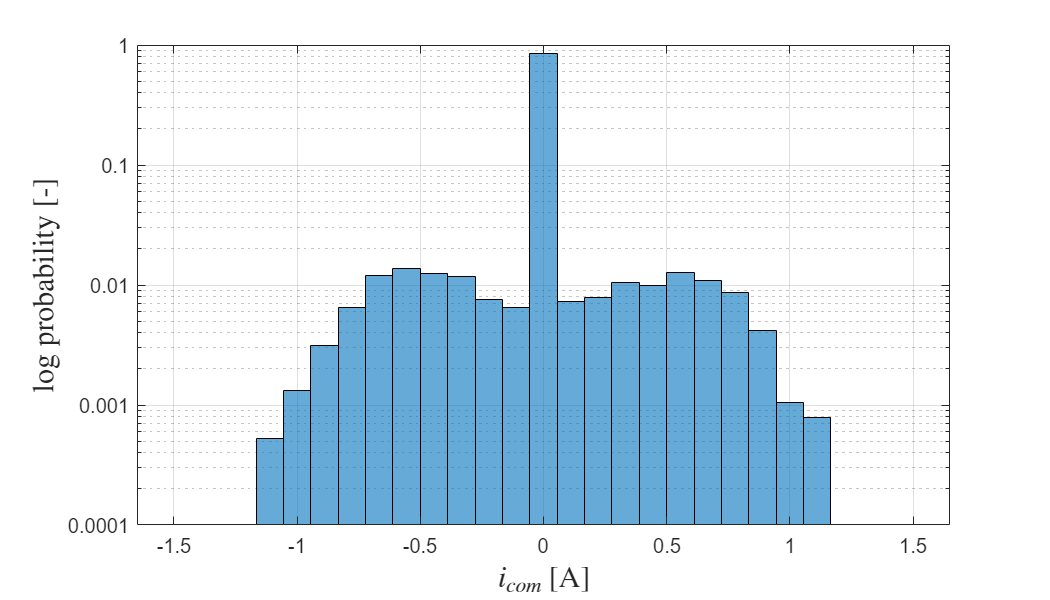

h.BinEdges = [-1.5:1.5];
h.NumBins = 27;
set(gca,'yscale','log')
yticklabels({'0.0001','0.001','0.01','0.1','1'})
grid on
xlabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
ylabel('log probability [-]', "FontSize", 15,'Interpreter','latex')

### Question 10

Define a reference track for $r_x(t)$

% t_range
t_range = [0,1];
syms t;

% r_x(t)
delta = 0.1;
A = 0.5;
f = 1;
r_x(t) = 200*t-100;
% r_x(t) = (-A/atan(1/delta))*atan(cos(2*pi*t*f)/delta) + A;
% r_x = @(t) t*0;
% calculate points to be plotted
t_points = linspace(t_range(1),t_range(2));

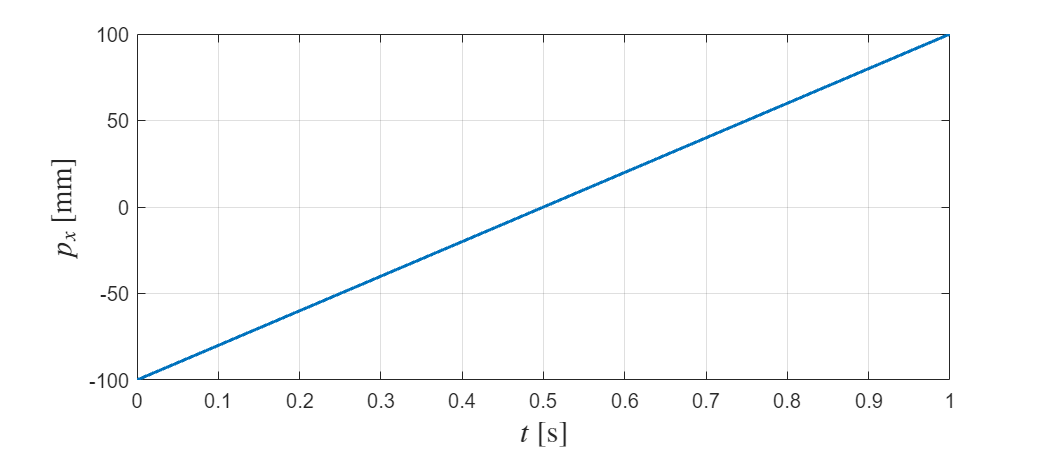

close all
figure
set(gcf,'position',[x0,y0,width,300])
fplot(r_x, t_range, 'LineWidth', 1.5)
grid on
xlabel('$t$ [s]', "FontSize", 15,'Interpreter','latex')
ylabel('$p_x$ [mm]', "FontSize", 15,'Interpreter','latex')
xlim(t_range)

Now define a reference track for $r_z(t)$

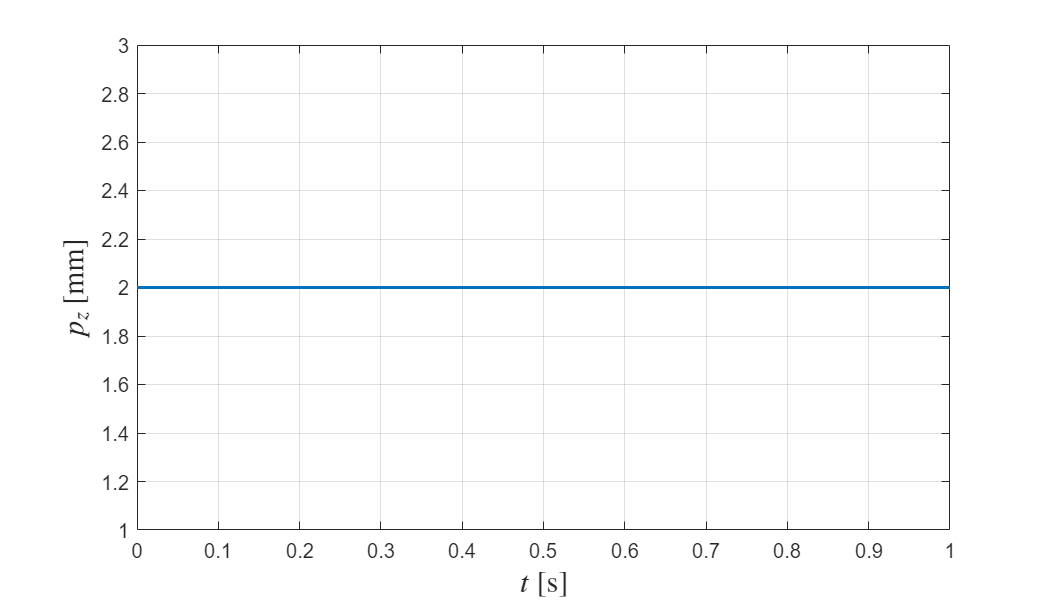

% r_x(t)
a = 1;
syms t

% r_z(t)
% delta = 0.1;
% A = 0.5;
% f = 1;
% r_z(t) = (-A/atan(1/delta))*atan(cos(2*pi*t*f)/delta) + A;
% r_z = @(t) t*0;
r_z = @(t) 2 + t*0;

% plot
close all
figure
set(gcf,'position',[x0,y0,width,height])
fplot(r_z, t_range, 'LineWidth', 1.5)
grid on
xlabel('$t$ [s]', "FontSize", 15,'Interpreter','latex')
ylabel('$p_z$ [mm]', "FontSize", 15,'Interpreter','latex')
xlim(t_range)

Calculate points for r_x and r_z

% number of timesteps
N = 1e3;
t0 = 0;             % [s]
t1 = 1;             % [s]
dt = (t1 - t0)/N;    % [s]

% time vector
t_vec = 0:dt:dt*(N-1); 

r_x_points = double(r_x(t_vec));
r_z_points = double(r_z(t_vec));

#### Now we create the for loop to run through the problem

#### Use objective: minimze P(x)

% matrix to hold the current vector for each timestep
i_com_r = zeros([3,K,N-2]);

% matrix to hold power at every step
P_com = zeros([3,N-2]);

% create normal distribution samples
n_x = normrnd(0, sqrt(0.5), [N,1]);
n_z = normrnd(0, sqrt(0.5), [N,1]);

% formula for F_x[k]
const = (m/(dt^2));
F_x = @(p_x, noise) const * (p_x(3) - 2*p_x(2) + p_x(1)) + noise;

% formula for F_z[k]
F_z = @(p_z, noise) const * (p_z(3) - 2*p_z(2) + p_z(1)) + m*g + noise;

% number of active coils at each timestep
active_coils = zeros([3, K, N-2]);

% loop over each timestep
for k = 2:N-1
    noise_x = n_x(k);
    noise_z = n_z(k);

    % fprintf('--- NEW INDEX [%d] ---', k);

    % get reference for x
    ref_x = [r_x_points(k-1), r_x_points(k),  r_x_points(k+1)];

    % get reference for z
    ref_z = [r_z_points(k-1), r_z_points(k),  r_z_points(k+1)];

    % calculate desired wrench vector [F_x, F_z, 0]
    w_desired = double([F_x(ref_x,noise_x); F_z(ref_z,noise_z); 0]);

    if sum(isnan(w_desired)) > 0
        fprintf("Got NaN at k=%d", k)
        break
    end
    
    % compute gamma matrix
    Gamma = Gm_px_f(r_x_points(k), r_z_points(k));
    
    % %%% - TARGET 1: MINIMIZE ABSORBED POWER - %%%
    i_com_1 = min_abs_power(R, Gamma, w_desired);
    % %%% - TARGET 1: MINIMIZE ABSORBED POWER - %%%

    % - TARGET 2: MINIMIZE MAXIMUM ABS CURRENT - %%%
    i_com_2 = min_max_abs_cur(Gamma, w_desired);
    % - TARGET 2: MINIMIZE MAXIMUM ABS CURRENT - % %

    % %%% - TARGET 3: MIMIZE NUMBER OF ACTIVE COILS - %%%
    i_com_3 = min_active_coils(Gamma, w_desired);
    % %%% - TARGET 3: MIMIZE NUMBER OF ACTIVE COILS - %%%

    % write i_com to i_com array
    i_com_r(1, :, k) = i_com_1;
    i_com_r(2, :, k) = i_com_2;
    i_com_r(3, :, k) = i_com_3;

    % write number of active coils to i_com array
    active_coils(1,:,k) = (abs(i_com_1) ~= 0);
    active_coils(2,:,k) = (abs(i_com_2) ~= 0);
    active_coils(3,:,k) = (abs(i_com_3) ~= 0);
    
    % power consumed by this system
    P_com(1,k) = double(i_com_1' * R * i_com_1);
    P_com(2,k) = double(i_com_2' * R * i_com_2);
    P_com(3,k) = double(i_com_3' * R * i_com_3);
end

Plot the power $P(x,z)$ for every timestep

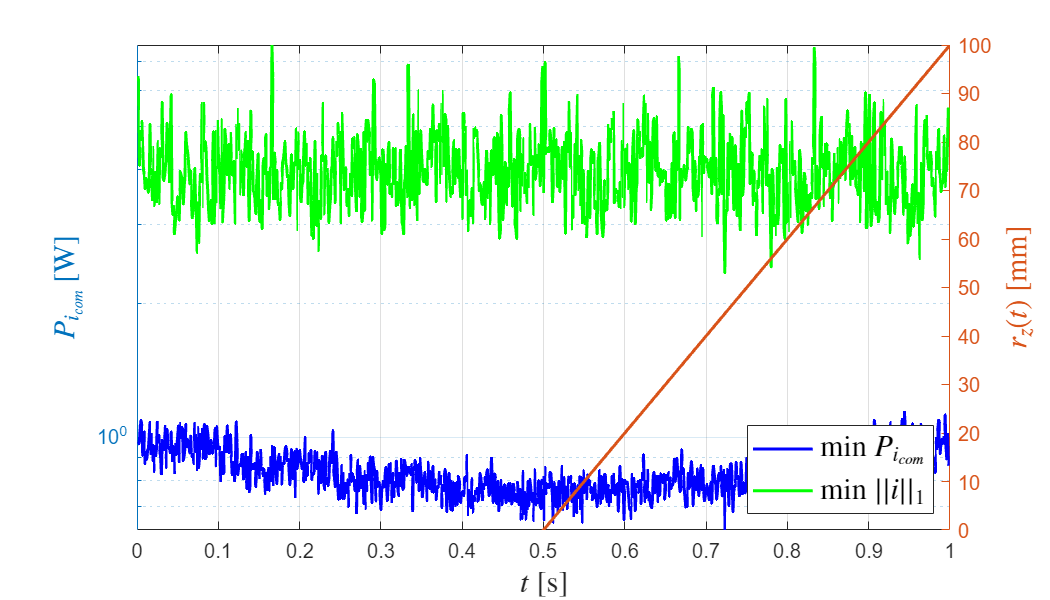

close all
figure(10)
set(gcf,'position',[x0,y0,width,height])
yyaxis left
semilogy(t_vec(1:end-1), min(squeeze(P_com(1,:)),1e10), '-', 'LineWidth', 1.5, 'Color', 'b')
hold on
semilogy(t_vec(1:end-1), min(squeeze(P_com(3,:)),1e10), '-', 'LineWidth', 1.5, 'Color', 'g')
hold off
ylabel('$P_{i_{com}}$ [W]', "FontSize", 15,'Interpreter','latex')
hold on
yyaxis right
ylabel('$r_z(t)$ [mm]', "FontSize", 15,'Interpreter','latex')
fplot(r_x, t_range, 'LineWidth', 1.5)
grid on
xlabel('$t$ [s]', "FontSize", 15,'Interpreter','latex')
legend('min $P_{i_{com}}$', 'min $||i||_1$', "FontSize", 15,'Interpreter','latex', 'Location', 'SE')
hold off

Make plot for current distributions $i_{com}$:

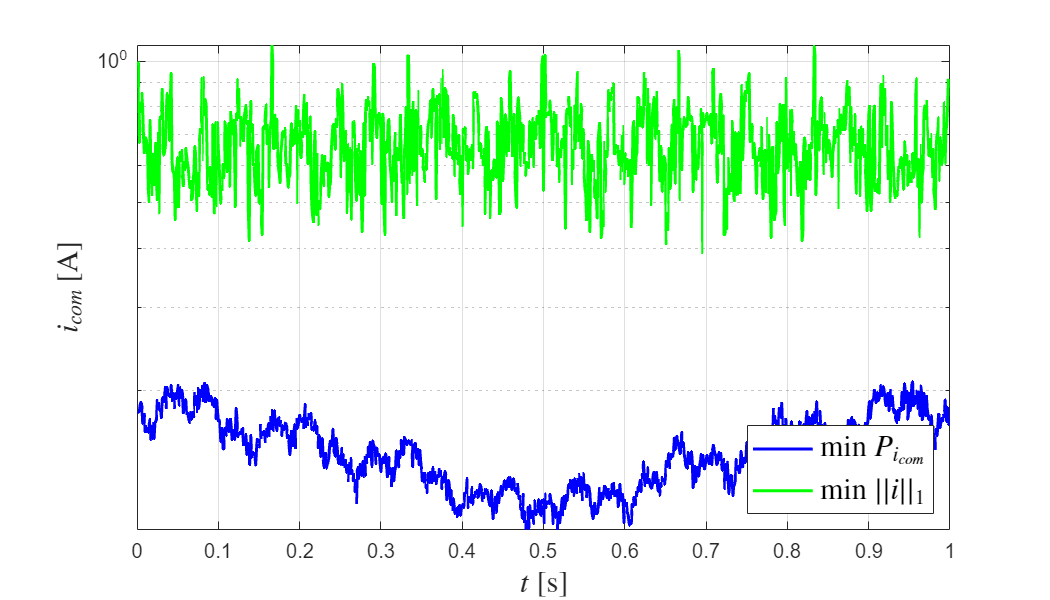

close all
figure
set(gcf,'position',[x0,y0,width,height])
semilogy(t_vec(1:end-1),squeeze(max(abs(i_com_r(1,:,:)))), 'LineWidth', 1.5, 'Color', 'b')
hold on
semilogy(t_vec(1:end-1),squeeze(max(abs(i_com_r(3,:,:)))), 'LineWidth', 1.5, 'Color', 'g')
hold off
grid on
ylabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
xlabel('$t$ [s]', "FontSize", 15,'Interpreter','latex')
legend('min $P_{i_{com}}$', 'min $||i||_1$', "FontSize", 15,'Interpreter','latex', 'Location', 'SE')

% legend
% ylim([1e-5, 1e2])

Current distributions, but plot raw values

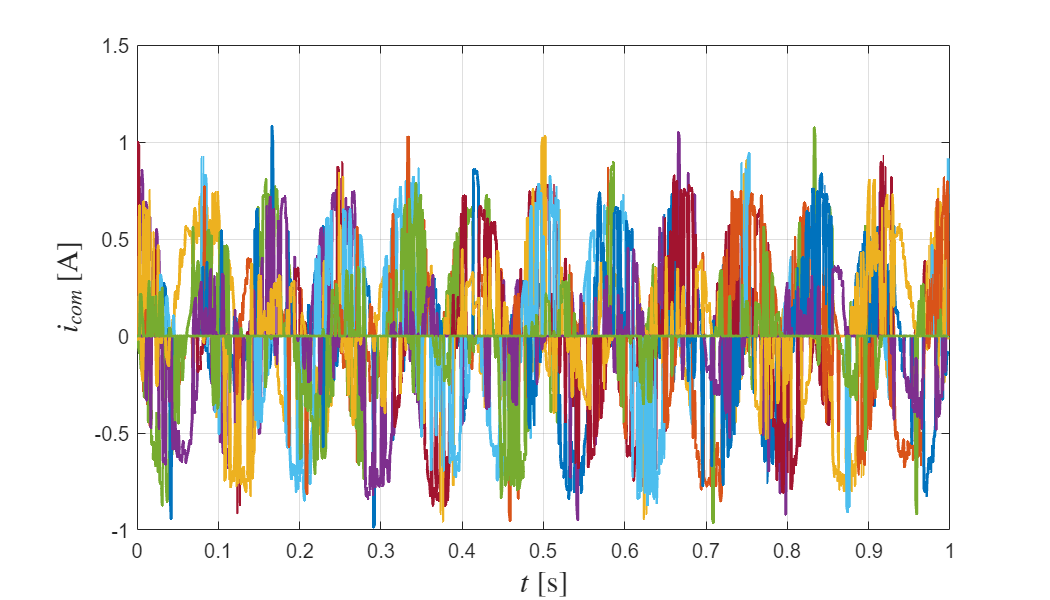

close all
figure
set(gcf,'position',[x0,y0,width,height])
plot(t_vec(1:end-1),squeeze(i_com_r(3,:,:)), 'LineWidth', 1.5)
hold off
grid on
ylabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
xlabel('$t$ [s]', "FontSize", 15,'Interpreter','latex')

% legend('min $P_{i_{com}}$', 'min $||i||_1$', "FontSize", 15,'Interpreter','latex', 'Location', 'SE')

Make histogram for number of active coils

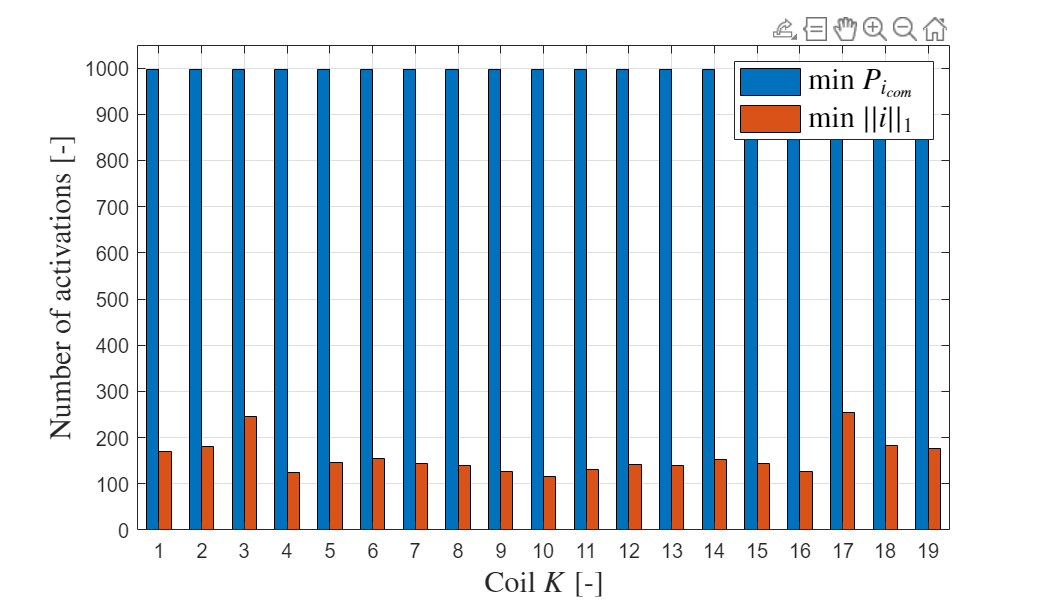

close all
figure
set(gcf,'position',[x0,y0,width,height])
bar(1:K,sum(active_coils([1,3],:,:),3),1)
xticks([1:K])
xlabel([1,K])
grid on
ylabel('Number of activations [-]', "FontSize", 15,'Interpreter','latex')
xlabel('Coil $K$ [-]', "FontSize", 15,'Interpreter','latex')
legend('min $P_{i_{com}}$', 'min $||i||_1$', "FontSize", 15,'Interpreter','latex', 'Location', 'NE')
ylim([0,1050])

close all
figure
set(gcf,'position',[x0,y0,width,height])
coil_mean = squeeze(movmean(i_com_r(1,:,:),5,3))

coil_mean =     0.0844    0.0951    0.1024    0.1289    0.1296    0.1282    0.1274    0.1260    0.1224    0.1199    0.1188    0.1175    0.1153    0.1160    0.1168    0.1159    0.1153    0.1135    0.1109    0.1066    0.1056    0.1027    0.1019    0.1016    0.1012    0.0997    0.0985    0.0954    0.0908    0.0886    0.0858    0.0836    0.0828    0.0831    0.0802    0.0792    0.0770    0.0742    0.0705    0.0684    0.0650    0.0621    0.0588    0.0562    0.0525    0.0487    0.0462    0.0435    0.0415    0.0403
   -0.0710   -0.0813   -0.0886   -0.1142   -0.1192   -0.1225   -0.1270   -0.1318   -0.1326   -0.1344   -0.1370   -0.1388   -0.1409   -0.1455   -0.1507   -0.1540   -0.1589   -0.1602   -0.1632   -0.1620   -0.1651   -0.1658   -0.1689   -0.1729   -0.1778   -0.1813   -0.1832   -0.1848   -0.1817   -0.1836   -0.1847   -0.1863   -0.1890   -0.1946   -0.1929   -0.1949   -0.1963   -0.1963   -0.1949   -0.1970   -0.1973   -0.1961   -0.1952   -0.1954   -0.1933   -0.1917   -0.1921   -0.1928   -0.1

coil_mean = (abs(coil_mean) >= 0.1)

coil_mean = 19×999 logical array
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   

h = heatmap(double(coil_mean(:,1:20:end)))

h =   HeatmapChart with properties:

        XData: {50×1 cell}
        YData: {19×1 cell}
    ColorData: [19×50 double]

  Show all properties


h.ColorbarVisible = 'off';
h.Interpreter = 'latex';
h.YLabel = 'Coil $K$ [-]'

h =   HeatmapChart with properties:

        XData: {50×1 cell}
        YData: {19×1 cell}
    ColorData: [19×50 double]

  Show all properties


h.XLabel = 'Position $p_x$ [mm]'

h =   HeatmapChart with properties:

        XData: {50×1 cell}
        YData: {19×1 cell}
    ColorData: [19×50 double]

  Show all properties


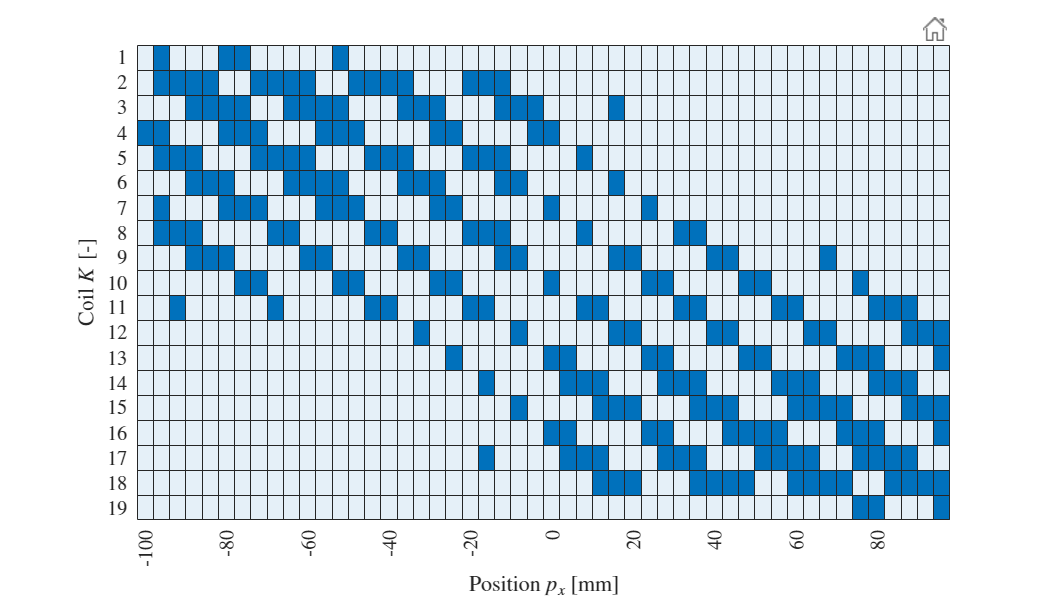

XLabels = -100:4:99;
% Convert each number in the array into a string
CustomXLabels = string(XLabels);
% Replace all but the fifth elements by spaces
CustomXLabels(mod(XLabels,10) ~= 0) = " ";
% Set the 'XDisplayLabels' property of the heatmap 
% object 'h' to the custom x-axis tick labels
h.XDisplayLabels = CustomXLabels;

grid on